### **5)** Consider the system shown in Figure 8–71. Assume that disturbances D(s) enter the system as shown in the diagram. Determine parameters K, a, and b such that the response to the unit-step disturbance input and the response to the unit-step reference input satisfy the following specifications: The response to the step disturbance input should attenuate rapidly with no steady-state error, and the response to the step reference input exhibits a maximum overshoot of 20% or less and a settling time of 2 sec.

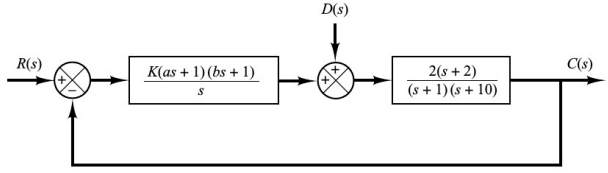

La función de transferencia del sistema viene dada por:


$$\frac{C\left(s\right)}{R\left(s\right)}=\frac{\textrm{Gc}\left(s\right)\textrm{Gp}\left(s\right)}{1+\textrm{Gc}\left(s\right)\textrm{Gp}\left(s\right)}$$


En este caso:


$$\frac{C\left(s\right)}{R\left(s\right)}=\frac{2K\left(a\;s+1\right)\left(b\;s+1\right)\left(s+2\right)}{s\left(s+1\right)\left(s+10\right)+2K\left(a\;s+1\right)\left(b\;s+1\right)\left(s+2\right)}$$


Reordenando se tiene:


$$\frac{C\left(s\right)}{R\left(s\right)}=\frac{\left(2K\;a\;b\right)s^3 +\left(2K\;a+2K\;b+4K\;a\;b\right)s^2 +\left(2K+2K\;a+4K\;b\right)s+4K}{s^3 +11s^2 +10s+\left(2K\;a\;b\right)s^3 +\left(2K\;a+2K\;b+4K\;a\;b\right)s^2 +\left(2K+2K\;a+4K\;b\right)s+4K}$$


Mientras que para la perturbación se tiene:


$$\frac{C\left(s\right)}{D\left(s\right)}=\frac{\textrm{Gp}\left(s\right)}{1+\textrm{Gc}\left(s\right)\textrm{Gp}\left(s\right)}$$


En este caso:


$$\frac{C\left(s\right)}{D\left(s\right)}=\frac{2s\left(s+2\right)}{s\left(s+1\right)\left(s+10\right)+2K\left(a\;s+1\right)\left(b\;s+1\right)\left(s+2\right)}$$


Reordenando se tiene:


$$\frac{C\left(s\right)}{D\left(s\right)}=\frac{{2s}^2 +4s}{s^3 +11s^2 +10s+\left(2K\;a\;b\right)s^3 +\left(2K\;a+2K\;b+4K\;a\;b\right)s^2 +\left(2K+2K\;a+4K\;b\right)s+4K}$$


## Solución númerica

Como el orden del numerador es igual al orden del denominador (FT propia) busco reducir el orden del primero para tener una FT estrictamente propia para que el sistema sea causal y estable al mismo tiempo. Hago 'a' = 0 y busco valores para K y b.


$$\frac{C\left(s\right)}{R\left(s\right)}=\frac{\left(2K\;b\right)s^2 +\left(2K+4K\;b\right)s+4K}{s^3 +\left(2K\;b+11\right)s^2 +\left(2K+4K\;b+10\right)s+4K}$$


close all; clear all; clc;

t = 0:0.01:4.1; % Tiempo.
k = 0;
for j = 1:30
    b(j) = 3.2 - j*0.1; % Variación del parámetro j.
    for h = 1:100
        K(h) = 40.2 - h*0.2; % Variación del parámetro K.
        num = [0 2*K(h)*b(j) (2*K(h)+4*K(h)*b(j)) 4*K(h)]; % Num FT.
        den = [1 (2*K(h)*b(j)+11) (2*K(h)+4*K(h)*b(j)+10) 4*K(h)]; % Den FT.
        y = step(num,den,t); % Respuesta al escalón unitario.
        m = max(y); % Valor máximo de la respuesta.
        s = 401; % Indice correspondiente al 'settling time'.
        while (y(s)>0.98 && y(s)<1.02) % ¿No es el instante el correspondiente al settling time?
            s = s - 1; % Entonces decremento 1.
        end
        ts = (s-1)*0.01; % Valor del settling time.
        if (m<1.20 && ts<2.0) % Si se cumplen las condiciones establecidads guardamos parámetros.
            k = k + 1;
            table(k,:) = [b(j) K(h) m ts];
        end
    end
end
sorsolution = sortrows(table,3) % Ordenamos la tabla en función del overshoot.

sorsolution =     3.1000   20.2000    0.9914    1.6300
    3.1000   20.4000    0.9915    1.6100
    3.0000   20.2000    0.9916    1.6500
    3.1000   20.6000    0.9916    1.5800
    3.0000   20.4000    0.9917    1.6300
    3.1000   20.8000    0.9917    1.5600
    3.0000   20.6000    0.9918    1.6000
    3.1000   21.0000    0.9918    1.5400
    2.9000   20.2000    0.9918    1.6700
    3.0000   20.8000    0.9918    1.5800


fprintf('Elijo los parámetros correspondientes a la fila 2996: a = 0, b = 0.2, K = 21\n')

Elijo los parámetros correspondientes a la fila 2996: a = 0, b = 0.2, K = 21


fprintf('El settling time tiene un valor de 1.77 s')

El settling time tiene un valor de 1.77 s


b = 0.2;
K = 21;
num1 = [0 2*K*b (2*K+4*K*b) 4*K]; % Num FT.
den1 = [1 (2*K*b+11) (2*K+4*K*b+10) 4*K]; % Den FT.
sys1 = tf(num1,den1) % Función de transferencia del sistema.

sys1 =
 
     8.4 s^2 + 58.8 s + 84
  ----------------------------
  s^3 + 19.4 s^2 + 68.8 s + 84
 
Continuous-time transfer function.



h1 = stepplot(sys1) % Comparación con entrada de referencia escalón.


h1 =

	resppack.timeplot



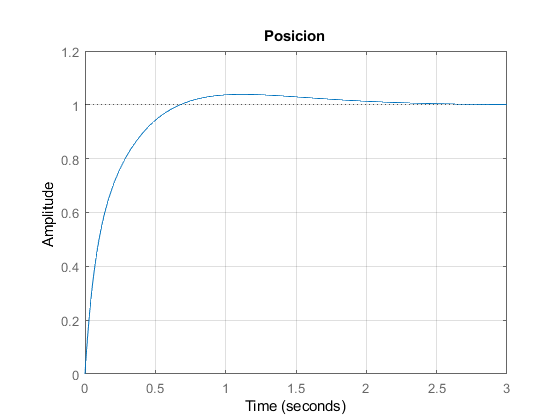

setoptions(h1,'Grid','on');
title('Respuesta al escalón unitario de referencia')


% Respuesta a escalón unitario de perturbación.
num2 = [0 2 4 0]; % Num FT.
den2 = [1 (2*K*b+11) (2*K+4*K*b+10) 4*K]; % Den FT.
sys2 = tf(num2,den2) % Función de transferencia del sistema ante perturbación.

sys2 =
 
          2 s^2 + 4 s
  ----------------------------
  s^3 + 19.4 s^2 + 68.8 s + 84
 
Continuous-time transfer function.



h2 = stepplot(sys2) % Comparación con entrada de perturbación escalón.


h2 =

	resppack.timeplot



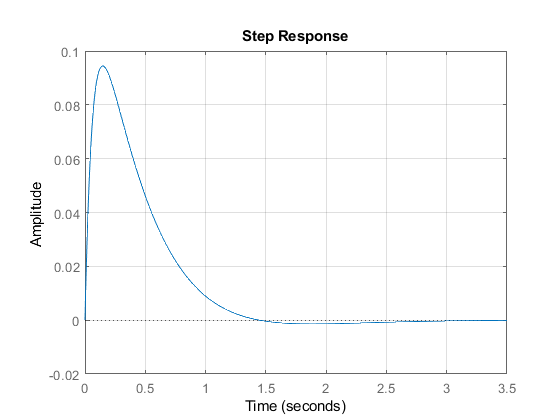

setoptions(h2,'Grid','on');

title('Respuesta al escalón unitario de perturbación')